### Input parameters:

e_radius = 6370; %earth's radius
domeRadius =  19100;  %satellite orbit radius
domeAlt = 0;
prompt = 'What is the receiver altitude? ';
altitude = input(prompt);
prompt_1 = 'How many satellites are in view? ';
num_satellites = input(prompt_1);
prompt_2 = 'What is the minimum angle of elevation? ';
elevation_angle = input(prompt_2);
prompt_3 = 'What is the User Equivelant Range Error Varience? (1-2m)? ';
UERE = input(prompt_3);
prompt_4 = 'Choose the number of iterations: ';
num_generations = input(prompt_4);
prompt_5 = 'What is the receiver latitude? ';
phi = input(prompt_5);
prompt_6 = 'What is the receiver longitude? ';
theta = input(prompt_6);

%genetic algorithm parameters
individual = [];
popsize = 1000;
num_survivors = 500;
num_mutations = 50;


### Calling Initial Functions to set up conditions:

R_coords = gen_points(e_radius + altitude, theta, phi); %generate receiver co-ordinates

sat_coords = []; %generate satellite co-ords
for i = 1:num_satellites
    sat_coords = [sat_coords ; gen_points(domeRadius,random_th(),random_phi(elevation_angle))];
end

### Plotting initial conditions:

grs80 = referenceEllipsoid('grs80','km');
[x,y,z] = sphere(20);
xEast  = domeRadius * x;
yNorth = domeRadius * y;
zUp    = domeRadius * z;
zUp(zUp < 0) = 0;
% figure('Renderer','opengl')
% surf(xEast, yNorth, zUp,'FaceColor','yellow','FaceAlpha',0.5); hold on
for i = 1:num_satellites
    [x,y,z] = sphere(20);
    x = x*1000;
    y = y*1000;
    z = z*1000;
%     surf(x + sat_coords(i,1),y + sat_coords(i,2),z + sat_coords(i,3),'FaceColor','green','FaceAlpha',0.5); hold on
end
hold off
axis equal

newsat = [];
[xECEF, yECEF, zECEF] ...
    = enu2ecef(xEast, yNorth, zUp,theta, phi, domeAlt, grs80);
% surf(xECEF, yECEF, zECEF,'FaceColor','yellow','FaceAlpha',0.5); hold on
for i = 1:num_satellites
    [x,y,z] = sphere(20);
    x = x*1000;
    y = y*1000;
    z = z*1000;
   
    [satnew_x, satnew_y, satnew_z] ...
    = enu2ecef(sat_coords(i,1), sat_coords(i,2), sat_coords(i,3), theta, phi, domeAlt, grs80);
%     surf(x + satnew_x,y + satnew_y,z + satnew_z,'FaceColor','green','FaceAlpha',0.5); hold on
    coord = [satnew_x satnew_y satnew_z];
    newsat = [newsat; coord];
end
axis equal

% figure('Renderer','opengl')
ax = axesm('globe','Geoid',grs80,'Grid','on', ...
    'GLineWidth',1,'GLineStyle','-',...
    'Gcolor',[0.9 0.9 0.1],'Galtitude',100);
ax.Position = [0 0 1 1];
axis equal off
view(3)

load topo
geoshow(topo,topolegend,'DisplayType','texturemap')
demcmap(topo)
land = shaperead('landareas','UseGeoCoords',true);
plotm([land.Lat],[land.Lon],'Color','black')
rivers = shaperead('worldrivers','UseGeoCoords',true);
plotm([rivers.Lat],[rivers.Lon],'Color','blue')

surf(xECEF, yECEF, zECEF,'FaceColor','yellow','FaceAlpha',0.3)
newsat = [];
for i = 1:num_satellites
    [x,y,z] = sphere(20);
    x = x*1000;
    y = y*1000;
    z = z*1000;
    
    [satnew_x, satnew_y, satnew_z] ...
    = enu2ecef(sat_coords(i,1), sat_coords(i,2), sat_coords(i,3), theta, phi, domeAlt, grs80);
%     surf(x + satnew_x,y + satnew_y,z + satnew_z,'FaceColor','green','FaceAlpha',0.5); hold on
    coord = [satnew_x satnew_y satnew_z];
    newsat = [newsat; coord];
end

### Calling GDOP Calculation for Initial Conditions:

[GDOP_init,HDOP_init,PDOP_init,TDOP_init] = genmatrices(num_satellites, newsat, R_coords, UERE)

GDOP_init = 2.9801

HDOP_init = 0.7532

PDOP_init = 2.0377

TDOP_init = 2.1745

### Optimization Time!!

#### Calling Optimazation function

population = gen_population(popsize,domeRadius, elevation_angle, num_satellites)

population = 	1.0e+04 *

    0.4915   -1.7141    0.6845
    0.0331   -0.0041    1.9097
    1.1698    1.3458    0.6845
    1.1088   -0.1756    1.5452
   -0.6104    1.7728    0.3644
    1.7438    0.7764    0.0667
   -0.6527    0.3618    1.7582
   -0.3439   -1.6180    0.9550
    1.2952    1.2078    0.7155
   -0.0874    1.6682    0.9260


current_fittest = 0;
fitest_sat = [0,0,0]

fitest_sat =      0     0     0


for i = 1:num_generations
    u_fitness = find_fitnesses(population, num_satellites);
    [r_fitness,I] = find_r_fitnesses(u_fitness);
    r_fitness = [r_fitness(:,2) I(:,2)];
    if r_fitness(1,1) > current_fittest
        current_fittest = r_fitness(1,1)
        fitest_sat = population(r_fitness(1,2):r_fitness(1,2)+num_satellites,:)
    end
    survivors = kill_off_the_weak(r_fitness, num_survivors);
    paired_parents = pair_up(survivors, population, num_satellites);
    children = meiosis(paired_parents, num_satellites);
    mutated_children = mutation(children, num_mutations, num_satellites);
    paired_parents;
    next_gen = [paired_parents ; mutated_children]; 
    population = next_gen;
end

current_fittest = 5.0136e+03

fitest_sat = 	1.0e+04 *

   -1.2078    0.4880    1.3969
   -1.5795   -0.5439    0.9260
   -1.2514    1.4395    0.1000
   -0.3817   -1.7959    0.5265
   -0.4896    0.5632    1.7582
   -0.3969    1.8671    0.0667
   -0.0446   -0.0495    1.9088
    0.6661   -1.2017    1.3268
    0.6984    1.2097    1.3026
    0.1910    0.5248    1.8265


current_fittest = 5.6790e+03

fitest_sat = 	1.0e+04 *

    0.7196   -1.2982    1.2020
   -0.6339    1.7415    0.4621
    1.3261   -0.6184    1.2277
   -0.9472    0.7400    1.4843
   -1.6854   -0.7504    0.4943
    0.8979    1.0701    1.3026
   -0.6133    1.5180    0.9837
    0.5666   -0.8724    1.6019
   -0.5039   -1.0331    1.5254
   -0.2823   -0.5541    1.8059


current_fittest = 5.6897e+03

fitest_sat = 	1.0e+04 *

    1.0048    1.5473    0.4943
    1.7559   -0.5926    0.4621
    0.1050   -1.5014    1.1759
    0.9391    0.5642    1.5646
    0.3949   -1.8580    0.1996
    1.2623   -0.9862    1.0403
   -0.9211    0.9211    1.3969
   -0.2158   -1.7577    0.7155
   -1.4045    1.2210    0.4297
    0.0382   -0.0546    1.9088


### Working with Optimized Satellites Now

% optimized_sats = population(length(population(:,1))-num_satellites:length(population(:,1)),:);
u_fitness = find_fitnesses(population, num_satellites);
[r_fitness,I] = find_r_fitnesses(u_fitness);
r_fitness = [r_fitness(:,2) I(:,2)];
    
%optimized_sats = population(r_fitness(1,2):r_fitness(1,2)+num_satellites,:);
optimized_sats = fitest_sat

optimized_sats = 	1.0e+04 *

    1.0048    1.5473    0.4943
    1.7559   -0.5926    0.4621
    0.1050   -1.5014    1.1759
    0.9391    0.5642    1.5646
    0.3949   -1.8580    0.1996
    1.2623   -0.9862    1.0403
   -0.9211    0.9211    1.3969
   -0.2158   -1.7577    0.7155
   -1.4045    1.2210    0.4297
    0.0382   -0.0546    1.9088


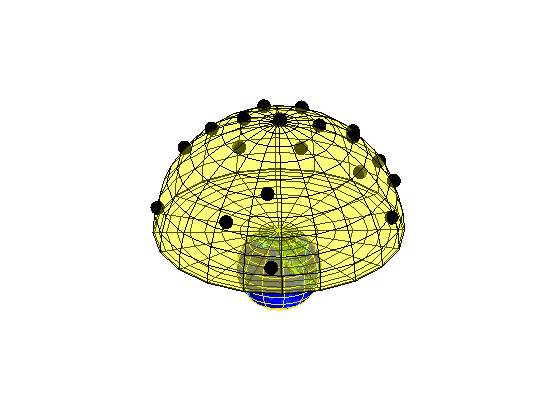

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0


newsat_opt = [];
for i = 1:num_satellites
    [x,y,z] = sphere(20);
    x = x*1000;
    y = y*1000;
    z = z*1000;
    
    [satnew_x, satnew_y, satnew_z] ...
    = enu2ecef(optimized_sats(i,1), optimized_sats(i,2), optimized_sats(i,3), theta, phi, domeAlt, grs80);
0
surf(x + satnew_x,y + satnew_y,z + satnew_z,'FaceColor','red','FaceAlpha',0.5); hold on
    coord = [satnew_x satnew_y satnew_z];
    newsat_opt = [newsat_opt; coord];
end

### GDOP calculation for optimized satellites:

[GDOP_opt,HDOP_opt,PDOP_opt,TDOP_opt] = genmatrices(num_satellites, newsat_opt, R_coords, UERE)

GDOP_opt = 2.8212

HDOP_opt = 0.7365

PDOP_opt = 1.8422

TDOP_opt = 2.1367

### Function to generate coordinates:

function out = gen_points(radius, th, phi)
    x_soln = radius*sin(deg2rad(phi))*cos(deg2rad(th));
    y_soln = radius*sin(deg2rad(phi))*sin(deg2rad(th));
    z_soln = radius*cos(deg2rad(phi));

    out = [x_soln y_soln z_soln];
end

function out = random_th()
    V = 0:360;
    out = V(randi([1 numel(V)]));
end

function out = random_phi(elevation_angle)
    V = 0:(90-elevation_angle);
    out = V(randi([1 numel(V)]));
end

function out = random_number(upper_end)
    V = 1:upper_end;
    out = V(randi([1 numel(V)]));
end

### DOP Calculation Function

function [GDOP,HDOP,PDOP,TDOP] = genmatrices(num_sat, sat_coords, receiver, UERE)

    all_coords = [];
    
    for i = 1:num_sat
        all_coords = [all_coords; sat_coords(i,1:3)];
    end
    
    Ri = all_coords - [0 0 0];
    
    S_R = all_coords - receiver;
    mag_ei = sqrt(sum(Ri.*Ri));
    ei = S_R./mag_ei;
    
    Gu = ones(num_sat,3);
    Gu = [(Gu + ei) ones(num_sat,1)];
    
    cov = inv(transpose(Gu)*Gu);
    
    GDOP = sqrt(cov(1,1) + cov(2,2) + cov(3,3) + cov(4,4))/UERE;
    PDOP = sqrt(cov(1,1) + cov(2,2) + cov(3,3))/UERE;
    HDOP = sqrt(cov(1,1) + cov(2,2))/UERE;
    TDOP = sqrt(cov(4,4))/UERE;
end

### Genetic Algorithm Functions

function population = gen_population(popsize, radius, elevation_angle, num_satellites)
    individual = [];
    temp = [];
    for i = 1:popsize
        for j = 1:num_satellites
            individual = [individual ; gen_points(radius, random_th, random_phi(elevation_angle))];   
        end
        temp = [temp ; individual];
        individual = [];
    end
    population = temp;
end

%finding a fitness (a distance in this case) and ascociating an index with
%the fitness -> index is population size/4
%each index that comes out of this function needs to be multiplied by 4 to
%find the relevant constellation of satellites
function unranked_fitnesses = find_fitnesses(population, num_satellites)
    unranked_fitness = [];
    for i = 1:length(population)/num_satellites %four satellites for one individual within population
        population(i:i+num_satellites-1,:);
        x = calc_distance(population(i:i+num_satellites-1,:), num_satellites);%retur min dist
        unranked_fitness = [unranked_fitness; [i x]]; %id then fitness
    end
    unranked_fitnesses = unranked_fitness;
end

%added in num_satellites to normalize distance
function total_distance = calc_distance(satellites,num_satellites)    
    total = 0;
    least = 100000000000;
    for i = 1:length(satellites)
        for j = 1:length(satellites)
            if i ~= j %i cannot be equal to j
                 dist = sqrt((satellites(i,1)-satellites(j,1)).^2 + (satellites(i,2)-satellites(j,2)).^2 + (satellites(i,3)-satellites(j,3)).^2);
              
                if (least > dist)
                    least = dist;
                end  
            end
            
        end
    end
    total_distance = least;
end

function [r_fitness,I] = find_r_fitnesses(u_fitness)
    [r_fitness,I] = sort(u_fitness, 'descend'); %sorts from most to least fit
end

%competativeness is the number of survivors to the next generation
function survivors = kill_off_the_weak(r_fitness, competativenss)
    survivors = r_fitness(1:competativenss,:);
end

function paired_parents = pair_up(survivors,population, num_satellites)
    indeces = survivors(:,2);
    grouped_parents_indeces = indeces(randperm(length(indeces)));
    temp = [];
    for i = 1:length(grouped_parents_indeces)  
        temp = [temp ; population((grouped_parents_indeces(i)-1)*num_satellites+1:(grouped_parents_indeces(i)-1)*num_satellites+num_satellites,:)];
    end
    paired_parents = temp;
end


function satellite = mutate(satellite, num_satellites)
    
    
    V = 0:pi/(4*10*num_satellites):(pi/(4*num_satellites));
    out_1 = V(randi([1 numel(V)]));
    out_2 = V(randi([1 numel(V)]));


    shift_distance = out_1;  
    shift_distance_2 = out_2;

    [theta,phi,r] = cart2sph(satellite(:,1), satellite(:,2), satellite(:,3));

theta = theta + out_1;
if phi > 90 - out_2
    phi = 90;
end
[X,Y,Z]=sph2cart(theta,phi,r);
satellite = [X Y Z];
end

function mutated_children = mutation(pop,num_mutations, num_satellites)
    for i = 1:num_mutations
        x = random_number(length(pop(:,1)));
        new_sat = mutate(pop(x,:), num_satellites);
        pop(x,:) = new_sat;
    end
    mutated_children = pop;
end


function children = meiosis(paired_parents, num_satellites)
    temp = [];
    for i = 1:length(paired_parents(:,1))/(2*num_satellites)
        set_1 = paired_parents(num_satellites*(i-1)+1:num_satellites*(i-1)+2*num_satellites,:);
        r1 = random_number(num_satellites-1);
        a1 = set_1(1:r1,:);
        a2 = set_1(num_satellites+1:num_satellites+r1,:);
        set_1(1:r1,:) = a2;
        set_1(num_satellites+1:num_satellites+r1,:) = a1;
        temp = [temp; set_1];
    end
    children = temp;
end